## Clear command prompt

clc;        % Clear Command Window text
clear;      % Clear all variables from workspace
close all;  % Close all open figure windows

## Import train dataset

### Walking

load sensorlog_walking.mat
walkAcceleration = Acceleration;
walkPosition = Position;
clear Acceleration;
clear Position;
clear Orientation

walkLabel = 'Walking';
walkLabel_acc = repmat(walkLabel, size(walkAcceleration, 1), 1);
walkLabel_pos = repmat(walkLabel, size(walkPosition, 1), 1);
walkAcceleration.Activity = walkLabel_acc;
walkPosition.Activity = walkLabel_pos;
clear walkLabel
clear walkLabel_pos
clear walkLabel_acc

### Sitting

load sensorlog_sitting.mat
sitAcceleration = abs(Acceleration);
sitPosition = Position;
clear Acceleration;
clear Position;

sitLabel = 'Sitting';
sitLabel_acc = repmat(sitLabel, size(sitAcceleration, 1), 1);
sitLabel_pos = repmat(sitLabel, size(sitPosition, 1), 1);
sitAcceleration.Activity = sitLabel_acc;
sitPosition.Activity = sitLabel_pos;
clear sitLabel
clear sitLabel_pos
clear sitLabel_acc

### Running

load sensorlog_running.mat
runAcceleration = abs(Acceleration);
runPosition = Position;
clear Acceleration;
clear Position;

runLabel = 'Running';
runLabel_acc = repmat(runLabel, size(runAcceleration, 1), 1);
runLabel_pos = repmat(runLabel, size(runPosition, 1), 1);
runAcceleration.Activity = runLabel_acc;
runPosition.Activity = runLabel_pos;
clear runLabel
clear runLabel_pos
clear runLabel_acc

### Ensure consistent data types

sitAcceleration.Activity   = string(sitAcceleration.Activity);
walkAcceleration.Activity  = string(walkAcceleration.Activity);
runAcceleration.Activity = string(runAcceleration.Activity);
sitPosition.Activity = string(sitPosition.Activity);
walkPosition.Activity = string(walkPosition.Activity);
runPosition.Activity  = string(runPosition.Activity);

## Machine Learning

### Use Position data as the predictor

allPosition = [sitPosition; walkPosition; runPosition];

allPosition = timetable2table(allPosition, "ConvertRowTimes", false);

classificationLearner

## **Example 1: But we know this is running**

load unknown(running).mat
unknownAcceleration = abs(Acceleration);
unknownPosition = Position

unknownPosition = 112×6 timetable
           Timestamp            latitude    longitude    altitude    speed    course     hacc 
    ________________________    ________    _________    ________    _____    ______    ______

    31-Oct-2025 15:03:14.000     1.3472      103.68       86.359        0         0     11.953
    31-Oct-2025 15:03:15.000     1.3472      103.68       98.495        0         0      5.746
    31-Oct-2025 15:03:16.000     1.3472      103.68        97.95        0         0      4.153
    31-Oct-2025 15:03:17.000     1.3472      103.68       92.853        0         0      3.806
    31-Oct-2025 15:03:18.000     1.3472      103.68       91.298        

clear Acceleration;

#### Predict the activity based on the model we built

justPos = timetable2table(unknownPosition, "ConvertRowTimes", false);

yfit = trainedModel.predictFcn(justPos); % predicted activity (Sitting, Walking, Running)

weight = 70;                     % kg
sampleInterval = 1;              % seconds per reading

activity = categorical(yfit);
activityTypes = categories(activity);
counts = countcats(activity);
durationMinutes = (counts * sampleInterval) / 60;   % minutes

#### Calculate calories burned per activity

calories = zeros(numel(activityTypes),1);
for i = 1:numel(activityTypes)
    calories(i) = caloriesBurned(activityTypes{i}, weight, durationMinutes(i));
end

Calories burned while Running for 1.9 min: 22.87 kcal



% Combine into a result table
T = table(activityTypes, durationMinutes, calories, ...
          'VariableNames', {'Activity','Duration_min','Calories_kcal'});
disp(T);

     Activity      Duration_min    Calories_kcal
    ___________    ____________    _____________

    {'Running'}       1.8667          22.867    




fprintf('\nTotal calories burned: %.2f kcal\n', sum(calories));


Total calories burned: 22.87 kcal


#### Calories Calculation function

function calories = caloriesBurned(activity, weight, duration)
% caloriesBurned calculates calories burned for basic activities.
% Usage:
%   calories = caloriesBurned('walking', 70, 30)

% Default MET values
if strcmpi(activity, 'Sitting')
    MET = 1.0;          % Sitting or resting
elseif strcmpi(activity, 'Walking')
    MET = 3.5;          % Normal walking
elseif strcmpi(activity, 'Running')
    MET = 10;          % Normal walking
else
    error('Activity must be "sitting" or "walking".');
end

% Calculate calories
calories = MET * weight * (duration / 60) * 1.05;

% Show result
fprintf('Calories burned while %s for %.1f min: %.2f kcal\n', ...
        activity, duration, calories);
end

#### Calculate calories burned

calories = zeros(numel(activityTypes),1);
for i = 1:numel(activityTypes)
    calories(i) = caloriesBurned(activityTypes{i}, weight, durationMinutes(i));
end

#### Create summary table

T = table(activityTypes, durationMinutes, calories, ...
          'VariableNames', {'Activity','Duration_min','Calories_kcal'});
disp(T);

     Activity      Duration_min    Calories_kcal
    ___________    ____________    _____________

    {'Running'}       1.8667          22.867    



fprintf('\nTotal calories burned: %.2f kcal\n', sum(calories));


Total calories burned: 22.87 kcal


### Distance and Step Calculation (SI units)

%% Step Count and Distance Calculation (in SI Units)
% Use your Position timetable
% e.g. Position = sensorlog_walking.Position;

lat = unknownPosition.latitude;
lon = unknownPosition.longitude;
timestamp = unknownPosition.Timestamp;

% --- Calculate total distance (in meters) ---
earthCirc = 40074275;  % Earth's circumference in meters
totalDist_m = 0;       % initialize

for i = 1:length(lat)-1
    lat1 = lat(i);
    lon1 = lon(i);
    lat2 = lat(i+1);
    lon2 = lon(i+1);

    % Distance in degrees between consecutive points
    degDist = distance(lat1, lon1, lat2, lon2);

    % Convert to meters
    dist_m = (degDist/360) * earthCirc;

    % Add up total
    totalDist_m = totalDist_m + dist_m;
end

% --- Step estimation ---
% Average adult stride length ≈ 0.75 m (you can adjust based on your height)
stride_m = 0.75;

steps = totalDist_m / stride_m;

fprintf('Total Distance Travelled: %.2f meters\n', totalDist_m);

Total Distance Travelled: 265.45 meters


fprintf('Estimated Steps: %.0f steps\n', steps);

Estimated Steps: 354 steps


### %% === 6. Dashboard Visualization ===

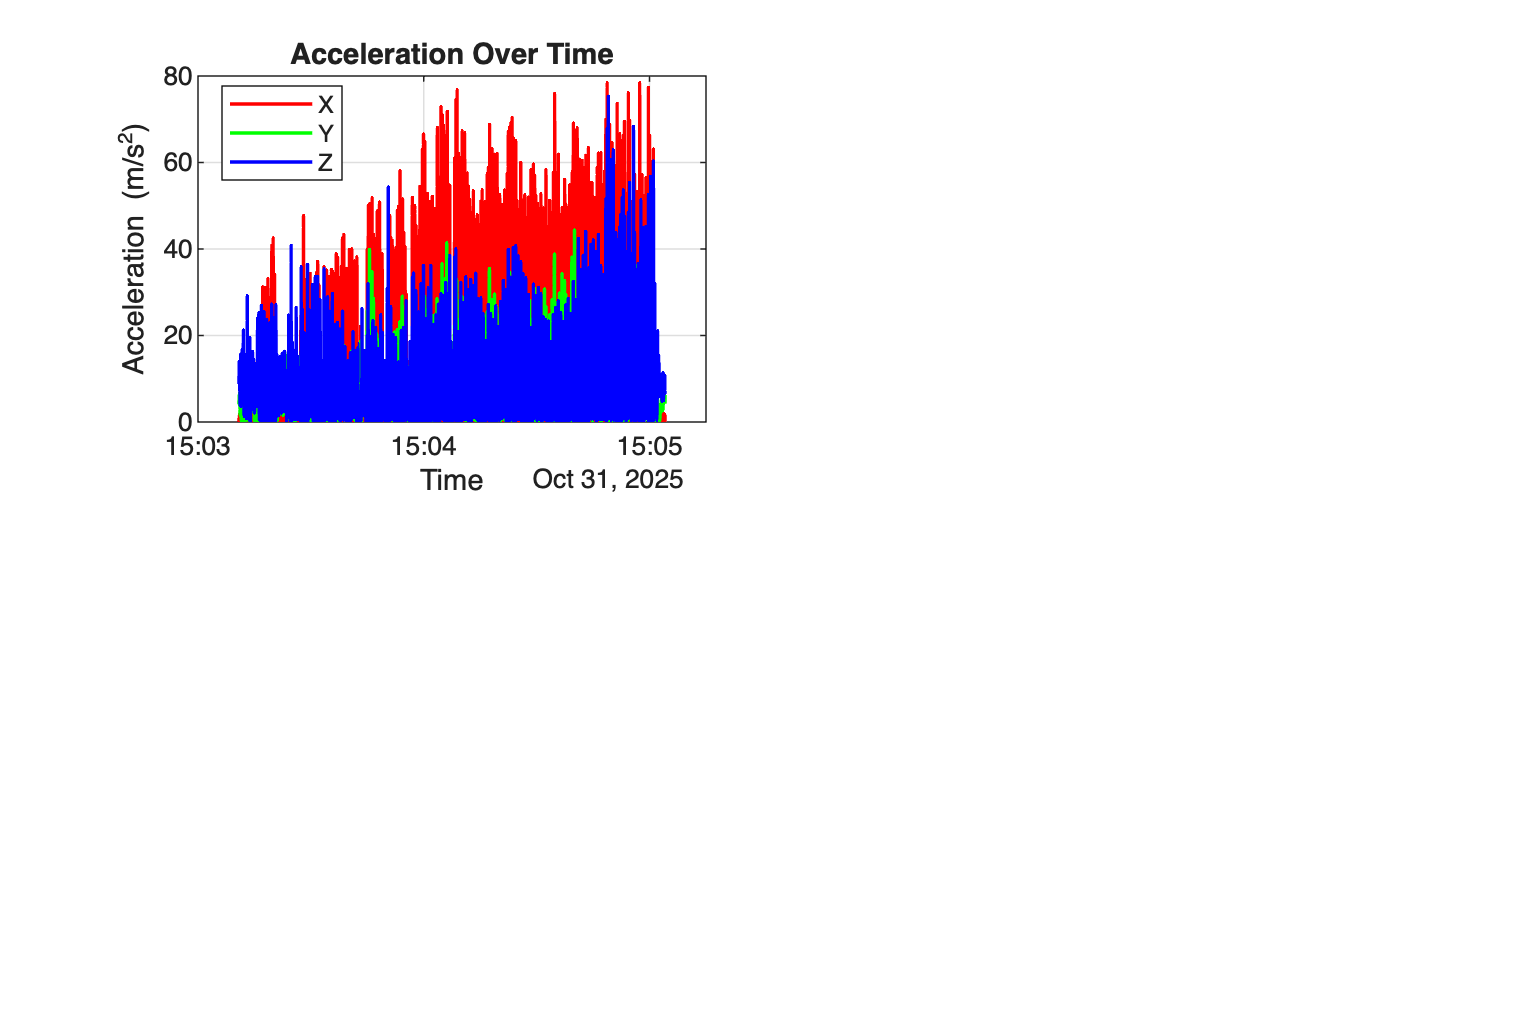

figure('Name','Fitness Tracker Dashboard','Position',[100 100 1200 800]);

% (1) Acceleration over time
t = unknownAcceleration.Timestamp;
subplot(2,2,1);
plot(t, unknownAcceleration.X, 'r', 'LineWidth', 1.2); hold on;
plot(t, unknownAcceleration.Y, 'g', 'LineWidth', 1.2);
plot(t, unknownAcceleration.Z, 'b', 'LineWidth', 1.2);
xlabel('Time');
ylabel('Acceleration (m/s^2)');
title('Acceleration Over Time');
legend('X','Y','Z','Location','best');
grid on; hold off;

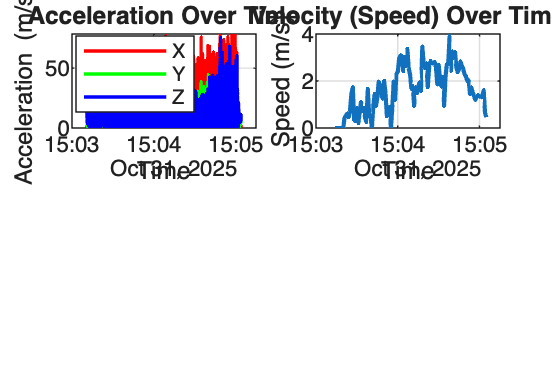

% (2) Velocity (Speed) over time
tPos = Position.Timestamp;
spd = Position.speed;
subplot(2,2,2);
plot(tPos, spd, 'LineWidth', 1.5);
xlabel('Time');
ylabel('Speed (m/s)');
title('Velocity (Speed) Over Time');
grid on;

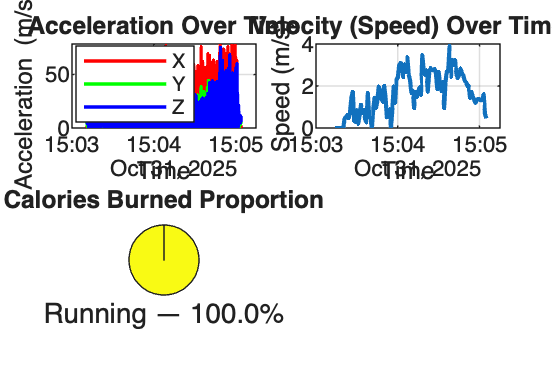


% (3) Calories burned proportion
vals = T.Calories_kcal;
names = string(T.Activity);
pct = 100 * vals / sum(vals);
labels = compose('%s — %.1f%%', names, pct);
subplot(2,2,3);
pie(vals, labels);
title('Calories Burned Proportion');
colormap(parula(numel(vals)));

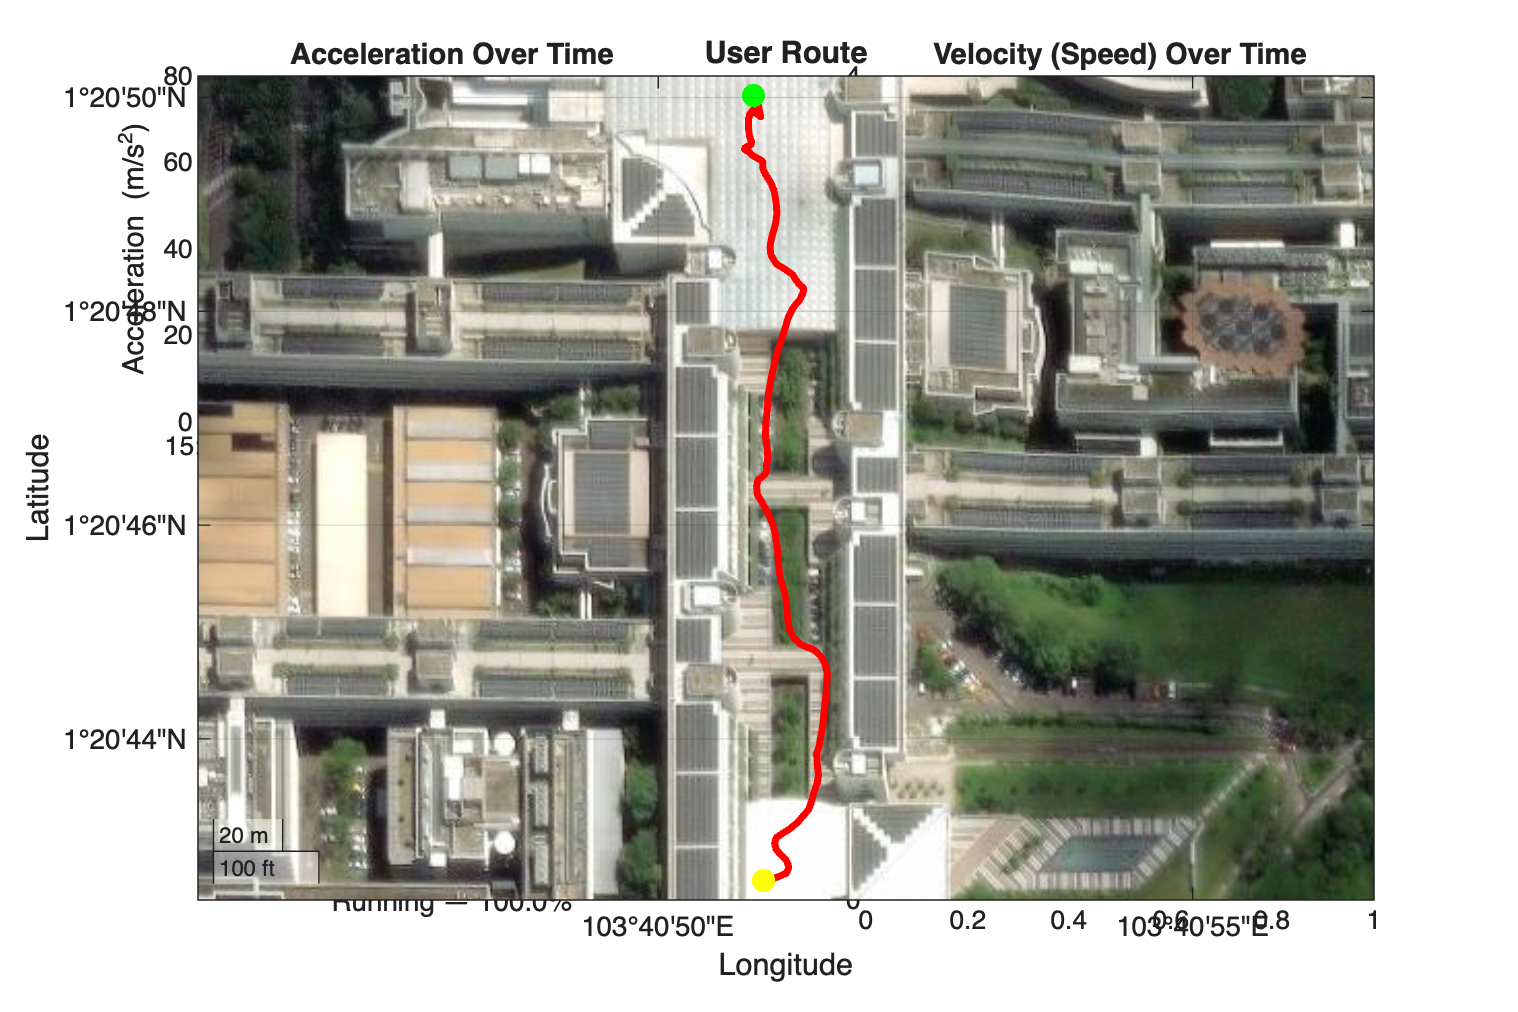

% (4) Route map
subplot(2,2,4);
gx = geoaxes;
geobasemap(gx, 'satellite');
hold(gx, 'on');
geoplot(gx, lat, lon, 'r', 'LineWidth', 2.5);
geoscatter(gx, lat(1), lon(1), 70, 'g', 'filled');     % start
geoscatter(gx, lat(end), lon(end), 70, 'y', 'filled'); % end
title(gx, 'User Route');
hold(gx, 'off');